# Acrobot Simulations

Simulate a single acrobot, where the acrobot parameters are as close as possible to the ones of the experiment.

Take the parameters as follows:

-  $m = \frac{m_t + m_l}{2} = \frac{0.2112 + 0.1979}{2} = 0.2046$ (the average of the masses of the torso and legs)

- $l = \frac{d_t + d_l + l_t + l_l}{4} = 0.1123$ (we make $l$ so that it is between the true center of mass $l_i$ and the actual length $d_i$ for $i \in {t,l}$, as an approximation of the real acrobot).

- $\bar{q}_a = 1$ so that $q_a = \arctan(I p_u) \in [-\frac{\pi}{2},\frac{\pi}{2}]$

To choose our control parameter, notice that $E_\pi$ intersects the $p_u$-axis at $p_u = \sqrt{60m^2gl^3}$. Suppose we want to achieve a max actuator angle of $q_a^\text{rot}$ at this intersection point; then the associated control value becomes $I = \tan(q_a^\text{rot})/\sqrt{60m^2gl^3}$.

If we choose $q_a^\text{rot}$ to be $\frac{\pi}{3}$, we get $I = 9.28$. We round this up to $I = 10$ and use this as our control value.

% Setup the real acrobot's parameters
mt = 0.2112; ml = 0.1979; % masses, kg
lt = 0.073;  ll = 0.083; % com, m
dt = 0.148;  dl = 0.145; % length of limbs, m
g = 9.81; % gravity, m/s^2

% Find the average mass, length, etc for the simple acrobot
m = mean([mt, ml]);
l = mean([lt, ll, dt, dl]);

% Set up the symbolic variables for the acrobot
qu = sym('qu','real'); % unactuated shoulder angle
pu = sym('pu','real'); % unactuated momentum
assumeAlso(-pi < qu);
assumeAlso(qu <= pi);

% Set the control parameters
qb = 1; % qbar, in [0,1]
qarot = pi/3; % desired qa at E_pi
I = ceil(tan(qarot)/sqrt(60*m^2*g*l^3));
qa = qb*atan(I*pu);

% Define the nominal energy function
E = pu^2/(10*m*l^2) + 3*m*g*l*(1-cos(qu));
Ef = matlabFunction(E,'vars',[qu, pu]);

% Set up the dynamics
Ipu1 = (1+I^2*pu^2);
su = sin(qu);
sua = sin(qu + qa);
ca = cos(qa);
su2sua = simplify(2*su + sua);
m2gl3 = m^2*g*l^3;

qud = simplify(...
    simplify((Ipu1*pu + m2gl3*qb*I*su2sua*(1+ca))) / ...
    simplify((m*l^2*Ipu1*(3+2*cos(qa)))) ...
    );
pud = simplify(-m*g*l*su2sua);

% Combine the dynamics and get them as a function
qpd = [qud; pud];
qpdf = matlabFunction(qpd,'vars',[qu, pu]);
% Convert it into a form that ode45 can use
fx = @(t,x)qpdf(wrapToPi(x(1)),x(2));

% Define the event for the ODE solver
E_event = @(t,qp) energyEvent(t,qp,Ef,Ef(pi,0));
baseOptions = odeset('RelTol',10e-14,...
                     'AbsTol',10e-14,...
                     'Events',E_event);
% Simulation time
T = 30;

## Part 1: Single Orbit Simulation

Initialize the acrobot at $q_u = \frac{\pi}{32}$ and show the orbit, tracking how long it takes the acrobot to remain outside of $E_\pi$. Also plot the nominal energy $E$.

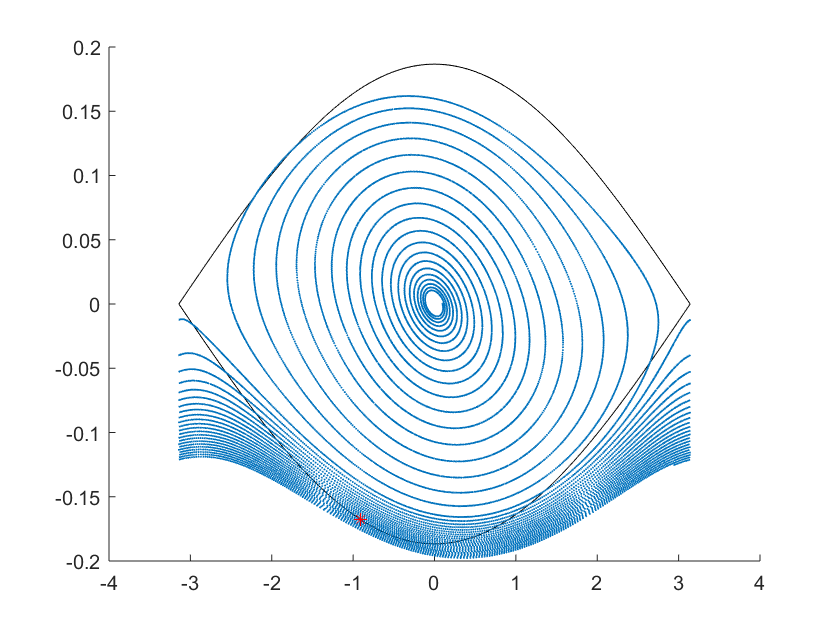

% Initial condition
qp0 = [pi/32;0];

% Simulate with an events trigger for when E = E_pi
sol = ode45(fx,[0,T],qp0,baseOptions);
% Wrap the qu values to the circle
sol.y(1,:) = wrapToPi(sol.y(1,:));
sol.ye(1,:) = wrapToPi(sol.ye(1,:));

% Plot the nominal E_pi
qs = linspace(-pi,pi,1000);
ps = sqrt(60*m^2*g*l^3 - 30*m^2*g*l^3*(1-cos(qs)));
orbitFig = figure;
hold on;
plot(qs,ps,'k',qs,-ps,'k');
% Now plot the orbit, with scatter point size 0.5 so
% it looks nice
scatter(sol.y(1,:),sol.y(2,:),0.5);
% Show the last time it exits the orbit
scatter(sol.ye(1,end),sol.ye(2,end),'r*');
hold off;

## Part 2: Monte-Carlo Simulation

Take as a metric the energy $E(q_u,p_u) = \frac{p_u^2}{10ml^2} + 3mgl(1 - \cos(q_u))$ of the nominal pendulum. Choose $\delta > 0$ and randomly initialize the acrobot inside of the sublevel set $E(\delta,0)$. Measure how long it takes for this to reach $E_\pi$ (i.e. for it to begin rotating) for $N$ trials and tabulate this using a monte-carlo approach.

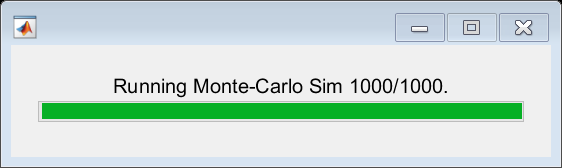

% Initialize the random number generator
rng('shuffle');

% Set the number of trials for the monte carlo method
N = 1000;

% Set the sublevel set as the energy level delta,
% where it is of the form E(delta,0)
delta = pi/32;

% Now initialize N points inside that energy sublevel set
% by taking a random value qu \in [-q0max,q0max] ...
q0s = -delta + 2*delta*rand(1,N);
% ... and find the value p(q0) which satisfies
% E(delta,0) = E(q0,p(q0))
% <-> 3mgl(1-cos(delta)) = p(q0)^2/(10ml^2)+3mgl(1-cos(q0))
% <-> p(q0)^2 = 30m^2gl^3(cos(q0)-cos(delta))
pq = sqrt(30*m^2*g*l^3*(cos(q0s) - cos(delta)));
% To set our initial conditions, choose a random pu value
% in [-p(q0), p(q0)].
p0s = -pq + 2*pq.*rand(1,N);
x0s = [q0s;p0s];

% Vector to store the first time we hit E_pi
tEpiFirst = zeros(1,N);
% Vector to store the final time we hit E_pi
tEpiLast = zeros(1,N);

% Set a progress bar for our simulation
bar = waitbar(0,'Please Wait...');
% Now simulate with the monte carlo method
for i = 1:N
    % Update the waitbar
    waitbar(i/N,bar,...
        sprintf('Running Monte-Carlo Sim %d/%d.',i,N));
    % Get the initial condition
    x0 = x0s(:,i);
    % Simulate using ode45
    soli = ode45(fx,[0,T],x0,baseOptions);

    % If the hitting time is empty, repeat this 
    % simulation with a longer time
    % First, set a variable to store the additional time
    Tadd = 0;
    while isempty(soli.xe)
        % Add 5 seconds to the "time to add" variable
        Tadd = Tadd + 5;
        % Update the progress bar to inform the user
        % that we are in this while-loop
        waitbar(i/N,bar,...
          sprintf('Repeating MC %d, adding %d seconds.',...
                  i, Tadd));
        % Repeat the simulation
        soli = ode45(fx,[0,T+Tadd],x0,baseOptions);
    end
    %
     % Extract both the first and final times
     % we stay outside E_pi
    tEpiFirst(i) = soli.xe(1);
    tEpiLast(i) = soli.xe(end);
end

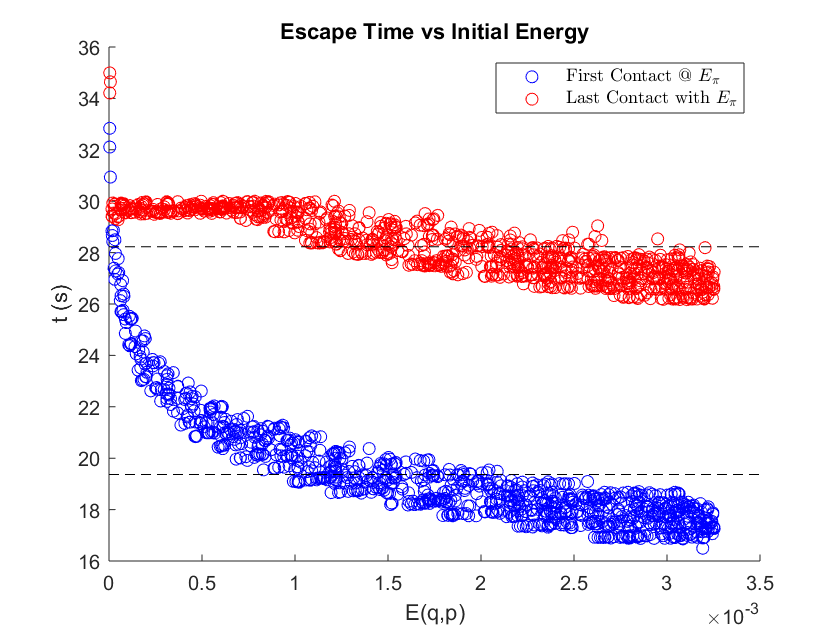


% Save all our data for the monte-carlo sims
mcData.delta = delta;
mcData.x0s = x0s;
mcData.tEpiFirst = tEpiFirst;
mcData.tEpiLast = tEpiLast;

% Get the average of the first and last hitting times
tFAvg = mean(tEpiFirst);
tLAvg = mean(tEpiLast);

% Plot first/last hitting time as a function of energy
% E(q0,p0)
figure;
hold on;
scatter(Ef(q0s,p0s),tEpiFirst,'b');
scatter(Ef(q0s,p0s),tEpiLast,'r');
% Show the average times
ax = axis;
plot(ax(1:2),[tFAvg,tFAvg],'k--');
plot(ax(1:2),[tLAvg,tLAvg],'k--');
hold off;
title('Escape Time vs Initial Energy');
xlabel('E(q,p)');
ylabel('t (s)');
legend({'First Contact with $E_\pi$',...
        'Last Contact with $E_\pi$'},...
        'Interpreter','latex');